# Homework 5

The purpose of this homework is to work carefully through a numeric/simulted solution to Bayes' Theorem. Bayes' Theorem reads:

P(signal|data) = P(data|signal)P(signal)/P(data)

Effectively the goal of this homework (and the lab) is to find P(signal|data).

Reading through Bayes' theorem it says that given a data reading, the probability it was produced by a given true signal (P(signal|data)), is equal to the probability of getting a particular data reading given a certain true signal (P(data|signal)) times the probability of the signal having a particular strength (P(signal)), divided by the probability of each data reading (P(data)).

This is just math, so is true. But in practice it is quite subtle how to use this. A few pointers:

- P(signal|data) is what we want to know. What was the probability distribution of the true signal given the measurement we have? Unfortunately it is hard to calculate from first principles.

- P(data|signal) Is usually easy to determine. If we have a signal-free background (see first 4 weeks of this class), we can *inject* fake signals of known strength and then simulate the observations in the presence of known (fake) signals. This means we can easily generate P(data|signal).

- P(signal) is called a prior. It is the probability the signal has a particular strength. Priors can be used to great effect, such as in combining the results of multiple particle physics experiments. But it is also the source of 90% of all statistical mistakes. It is *incredibly* dangerous. Almost all of the time—and always in this class—we will want a weak/uniform prior. One of the most dangerous bits of using Bayes' Theorem is that it is easy to have an implicit prior which will give you the wrong answer and you don't know why.

- P(data) in the denominator is almost always just a normalization factor, and is often dropped. This means the result will have to be renormalized, usually by making sure the full P(signal|data) integrates to one.

So the homework is to numerically work through this equation.

## Problem 1

*First start by throwing a signal-free background. For Problem 1 choose a Normal distribution with some modest σ, say in the range 2-5. Create a million background events.*

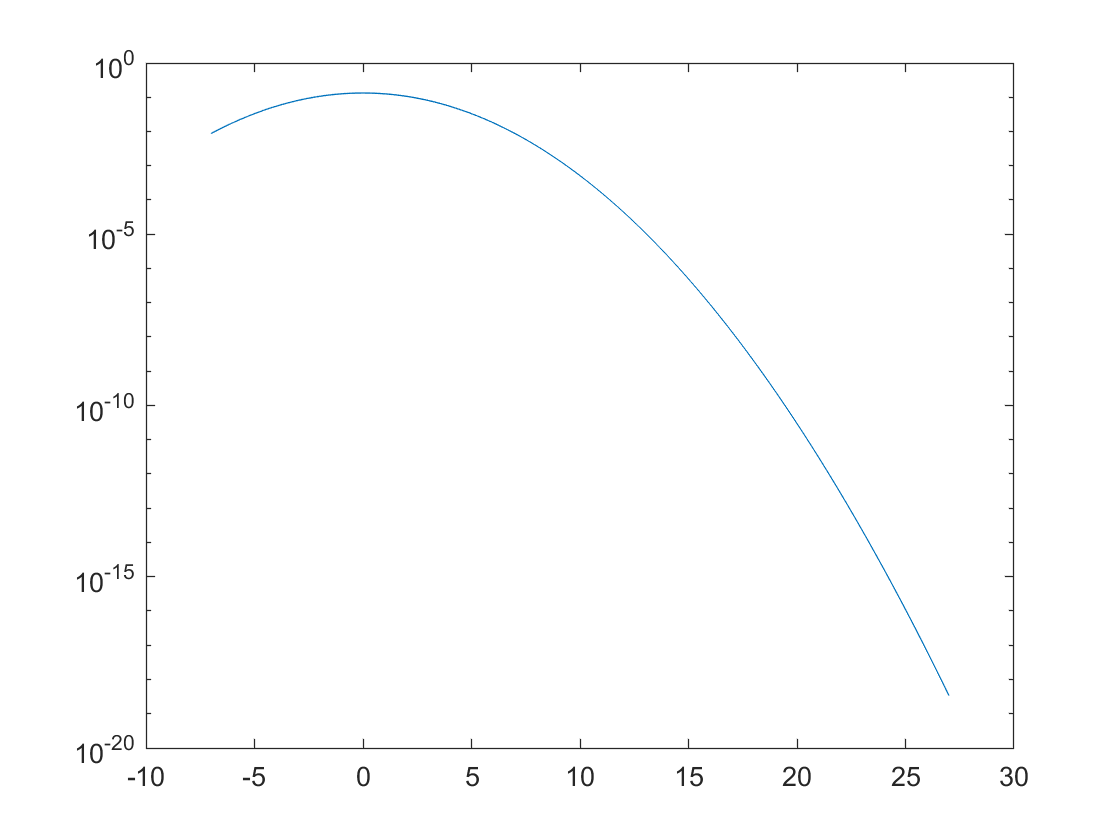

x = [-7:0.000034:27];
nor = makedist('Normal',"mu",0,"sigma",3);
normal = pdf(nor,x);
stairs(x,normal)
set(gca,'Yscale','log')

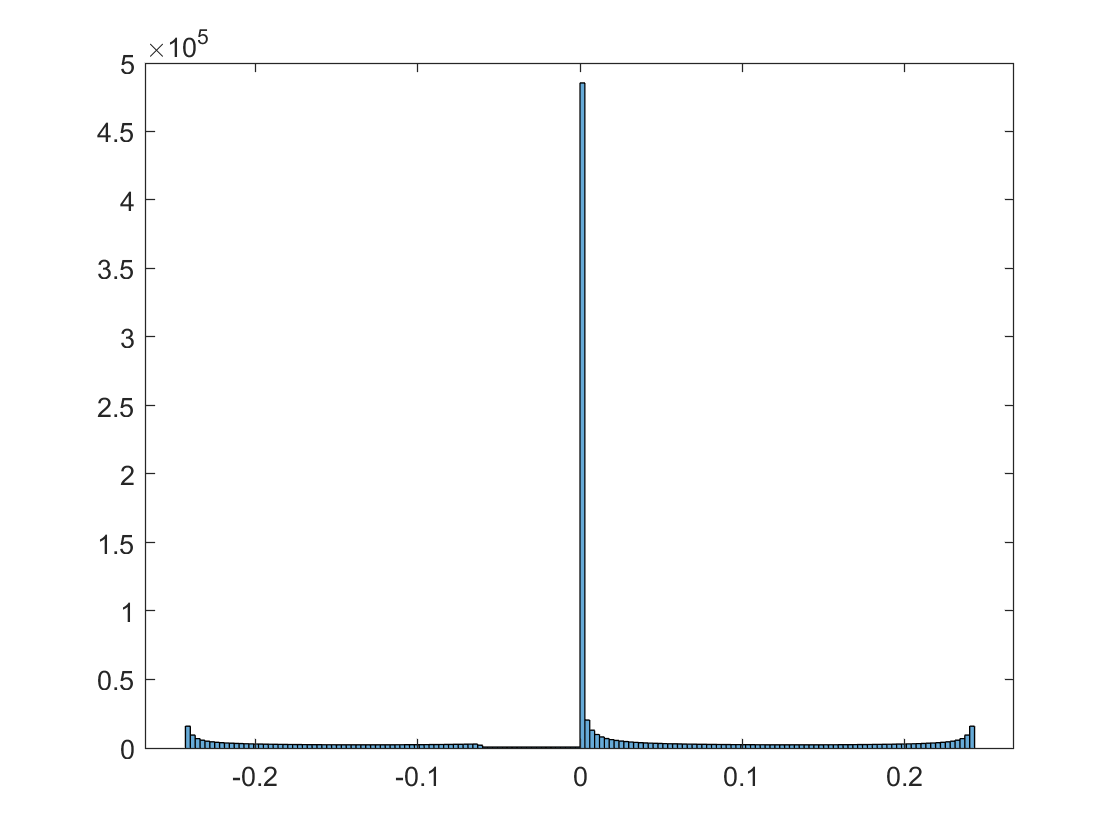

background = [x.*normal];
histogram(background)

*Now we need to make some signal. Let us choose to make signals of random strength on the interval of 0-20. Now it is critically important that you throw these using a uniform distribution. A uniform distribution means that the signal is equally likely to be small/faint (near zero) as large/bright (near 20). Mathematically this is the P(signal) in the equation. If you use another way of simulating signals that does not have a uniform distribution, you are injecting an implicit prior (very, very bad).*

*Now add your signal to your background to create fake data readings. Since you know what the true signal was for each data reading, and you used a flat prior, you now have P(data|signal)P(signal).*

*Now make one of the 2D histograms as shown in class. Here we want to histogram the signal vs. the simulated data readings. There are a couple of ways to do this, but it will be easier later if you define your bin edges explicitly, make a histogram, then plot it. Here is the code I used for the plot in class:*

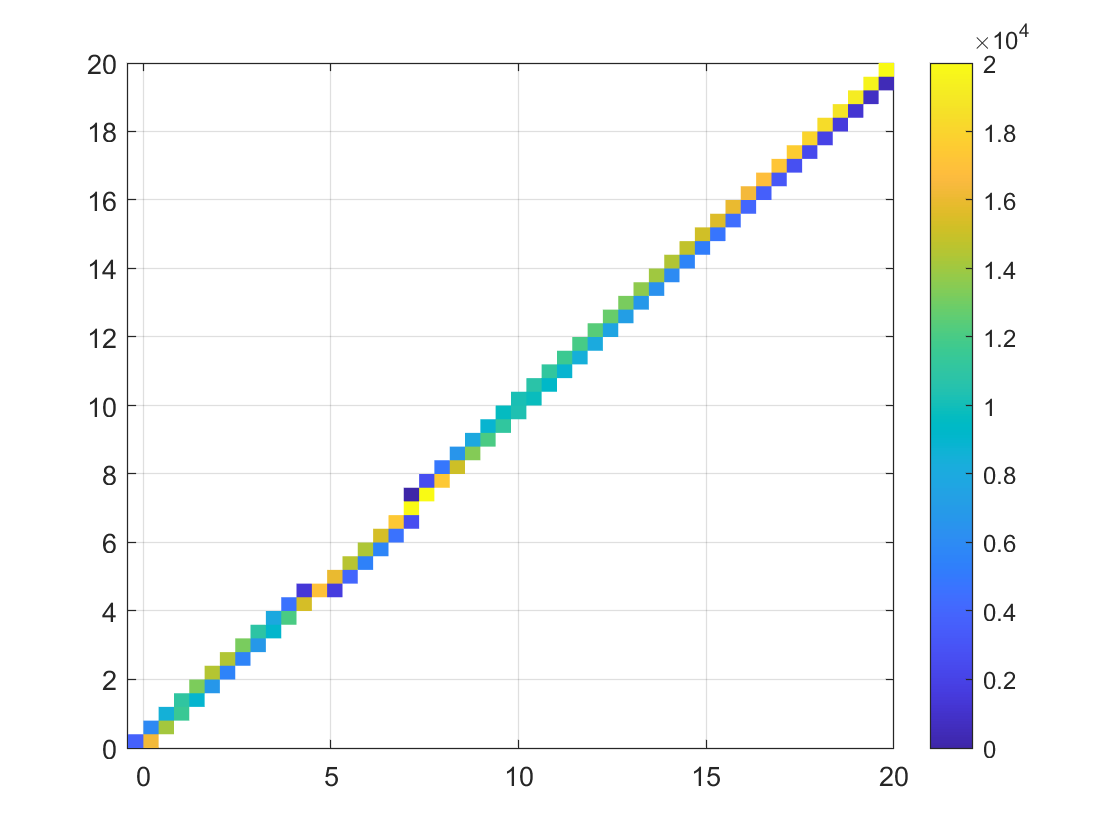

tsignal = zeros(1,length(x));
for i = 1:length(x)
    tsignal(i) = 0 + (i-1)*20/length(x);
end

data = background + tsignal;
histogram2(data,tsignal,"DisplayStyle","tile","NumBins",[50,50])
colorbar

`Ok I tried out a bunch of different things, but I can't figure out how to plot the histogram like in class. Are both axes supposed to be matrices with 20 separate distributions for each row???`

**Problem 1b**

*Select a true injected signal and plot P(d|s). (Use a stair style plot). Label your plot and clearly explain what you are plotting and how to interpret it. [Hint: this was also shown in class.]*

P(d|s) is the plot of the probability distribution for data values given a particular true signal. Shown by a horizontal slice on the actual histogram. 

**Problem 1c**

*Select an observed data value and plot P(s|d). (Use a stair style plot). Label your plot and clearly explain what you are plotting and how to interpret it.*

P(s|s) shows the probability distribution for the true signal given a specific data point. Shown by a vertical slice on the observed vs. true signal histogram. 

## Problem 2

Now repeat the above, but with a background with non-zero mean. The easiest way would be to still have Guassian distribution but with a non-zero mean. [Hint: move it by at least a couple of σσ]. Reproduce the graphs above. Lastly overplot the P(d|s) and P(s|d) plots. Why are they not centered on the same value? Explain carefully.